# Actividad Práctica N°2: Diseño de controladores en variables de estado en tiempo continuo

## Caso de estudio 1. Sistema de tres variables de estado

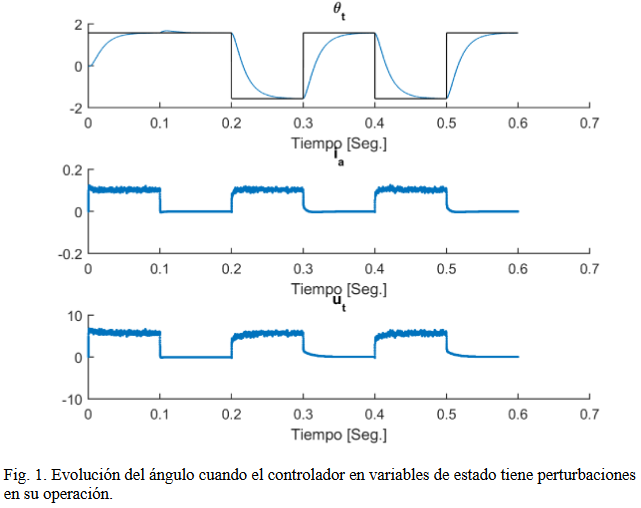

Dadas las ecuaciones del motor de corriente continua con torque de carga $T_L$ no nulo, con los parámetros:

- 
$$L_{\mathrm{AA}} =5\;{10}^{-3}$$


- 
$$J=0\ldotp 004$$


- 
$$R_A =0\ldotp 2$$


- 
$$B_m =0\ldotp 005$$


- 
$$K_i =6\ldotp 5\;{10}^{-5}$$


- 
$$K_m =0\ldotp 055$$



$$\frac{{\mathrm{di}}_a }{\mathrm{dt}}=-\frac{R_A \;}{L_{\mathrm{AA}} }i_a -\frac{K_m \;}{L_{\mathrm{AA}} }\omega {\;}_r +\frac{1\;}{L_{\mathrm{AA}} }v_a$$



$$\frac{d\omega {\;}_r }{\mathrm{dt}}=\frac{K_i \;}{J}i_a -\frac{B_m \;}{J}\omega_r -\frac{1\;}{J}T_L$$



$$\frac{d\theta {\;}_t }{\mathrm{dt}}=\omega_r$$


- Implementar un sistema en variables de estado que controle el ángulo del motor, para consignas de $\frac{\pi }{2}$ y $-\frac{\pi }{2}$ cambiando cada 2 segundos y que el $T_L$ de $1\ldotp 15\;10{\;}^{-3}$ aparece sólo para $\frac{\pi }{2}$ y para $-\frac{\pi }{2}$ es nulo. Hallar el valor de integración de Euler adecuado. El objetivo es mejorar la dinámica del controlador que muestra la Fig. 1.

- Considerar que no puede medirse la corriente y sólo pueda medirse el ángulo, por lo que debe implementarse un observador. Obtener la simulación en las mismas condiciones que en el punto anterior, y superponer las gráficas para comparar.

Se comienza definiendo las constantes:

Laa = 5e-3;
J = 0.004;
Ra = 0.2;
Bm = 0.005;
Ki = 6.5e-5;
Km = 0.055;

Ahora la representación matricial en variables de estado:

A = [-Ra/Laa -Km/Laa 0; Ki/J -Bm/J 1/J; 0 1 0]

A =   -40.0000  -11.0000         0
    0.0162   -1.2500  250.0000
         0    1.0000         0


B = [1/Laa 0; 0 -1/J; 0 0]

B =    200     0
     0  -250
     0     0


C = [0 0 1]

C =      0     0     1


D = [0 0]

D =      0     0


Se obtiene la función de transferencia para el torque:

sys = ss(A,B,C,D)

sys =
 
  A = 
            x1
   x1      -40
   x2  0.01625
   x3        0
 
            x2
   x1      -11
   x2    -1.25
   x3        1
 
            x3
   x1        0
   x2      250
   x3        0
 
  B = 
         u1    u2
   x1   200     0
   x2     0  -250
   x3     0     0
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.



GTheta = tf(sys)

GTheta =
 
  From input 1 to output:
               
           3.25
               
  ----------------------
                        
  s^3 + 41.25 s^2       
                        
          - 199.8 s     
                        
                  - 1e04
                        
 
  From input 2 to output:
                    
      -250 s - 10000
                    
  ----------------------
                        
  s^3 + 41.25 s^2       
                        
          - 199.8 s     
                        
                  - 1e04
                        
 
Continuous-time transfer function.



Se puede ver que la función de transferencia está dada en forma de matriz, ya que se está ante un sistema del tipo MIMO.

La matriz de controlabilidad del sistema es:

M = [B(:,1) A*B(:,1) A^2*B(:,1)]

M = 	1.0e+05 *

    0.0020   -0.0800    3.1996
         0    0.0000   -0.0013
         0         0    0.0000


Para comprobar controlabilidad:

if(rank(M) == rank(A))
    disp('Sistema Controlable')
else
    disp('Sistema No Controlable')
end

Sistema Controlable


El polinomio carácterístico del sistema es:

pA = poly(A)

pA = 	1.0e+04 *

    0.0001    0.0041   -0.0200   -1.0000


Ahora, para obtener el controlador. Haciendo uso de Sylvester:

W = [pA(3) pA(2) 1; pA(2) 1 0; 1 0 0]

W =  -199.8212   41.2500    1.0000
   41.2500    1.0000         0
    1.0000         0         0


T = M*W

T = 	1.0e+04 *

   -5.0000    0.0250    0.0200
    0.0000    0.0003         0
    0.0003         0         0


Los autovalores de la matiz A son los polos a lazo abierto del sistema, ya que el polinomio característico es la ecuación característica, por ello, se tiene:

eig(A)

ans =   -39.9945
  -16.4527
   15.1972


Para mejorar la respuesta del sistema, se introducen polos para lazo cerrado que estén alejados por lo menos una decada, de forma de obtener transitorios más cortos. Además, es posible ver que existe un polo positivo, lo que implica que a priori el sistema es inestable.

p1 = -500;
p2 = -1000;
p3 = -10000;
poles = [p1 p2 p3];

Con estos nuevos polos, se pretende armar una nueva función $\alpha \;$:

alphaf = poly(poles)

alphaf = 	1.0e+09 *

    0.0000    0.0000    0.0155    5.0000


Ahora se hace uso de la función derivada de Cayley Hamilton, de la siguiente forma:

K = (fliplr(alphaf(2:end)-pA(2:end))*inv(T))

K = 	1.0e+09 *

    0.0000    0.0048    1.5393


Con los siguientes polos a lazo cerrado, que deberían ser los planteados anteriormente:

sysT = A-B(:,1)*K;
eig(sysT)

ans = 	1.0e+04 *

   -1.0000
   -0.1000
   -0.0500


Ahora entonces se obtiene G:

G = -inv(C*inv(sysT)*B(:,1))

G = 1.5385e+09

Para hallar el período de integración por Euler entonces se obtiene lo siguiente:

tr = log(0.95)/min(eig(sysT))

tr = 5.1293e-06

El tiempo de integración debe ser menor al $t_R$ calculado, se toma entonces $1\;{10}^{-6}$.

Ahora, obtenido el período de integración por Euler, se procede a simular el sistema. Para ello, primero se declaran todas las variables de interés que serán utilizadas para la simulación.

h = 1e-6;
T = 20;
Kmax = T/h;
t = linspace(0,T,Kmax);
thetaRef = pi/2;
torqueRef = 1.15e-3;
ia(1) = 0;
theta(1) = 0;
omega(1) = 0;
omegaP(1) = 0;
reference(1) = thetaRef;
xop = [0;0;0];
x = [ia(1); omega(1); theta(1)];
xo = [0;0;0];
stateVector = [ia(1);omega(1);theta(1)];
u(2,:) = 0;
index = 0;
TL = torqueRef;

Ahora, la simulación propiamente dicha.

for i = 1:Kmax-1
    index = index+h;
    if(index < 10)
        TL = torqueRef;
        thetaInput = thetaRef;
    else
        TL = 0;
        thetaInput = -thetaRef;
    end
    reference(i) = thetaInput;
    u(:,i) = [-K*stateVector+G*reference(i);TL];
    xp = A*(x-xop)+B*u(:,i);
    x = x+xp*h;
    Y = C*x+D*u(:,i);
    ia(i+1) = x(1);
    omega(i+1) = x(2);
    theta(i+1) = x(3);
    stateVector = [ia(i);omega(i);theta(i)];
end
u(:,i+1) = u(:,i);
u = u(1,:);
reference(i+1) = reference(i);

Se grafica entonces la salida del sistema.

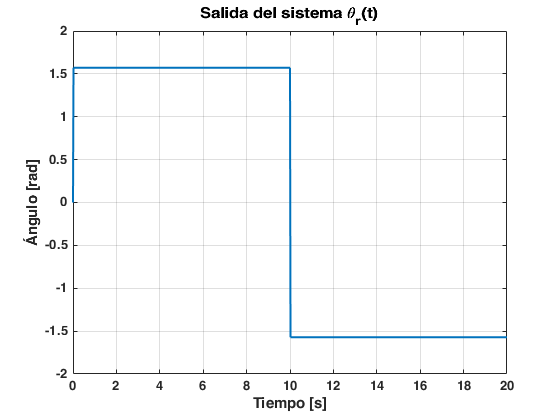

plot(t,theta,'LineWidth',1.5);
title('Salida del sistema \theta_r(t)')
xlabel('Tiempo [s]')
ylabel('Ángulo [rad]')
grid

Luego, la figura siguiente muestra la acción de control.

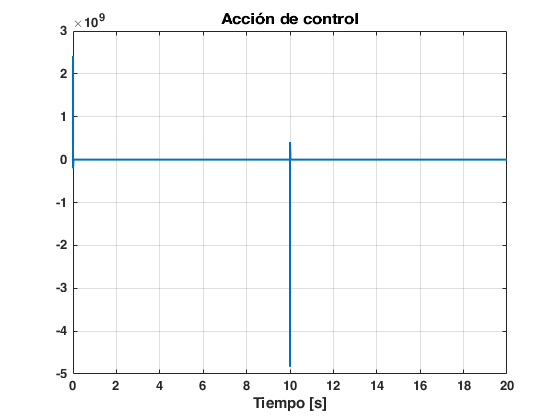

plot(t,u,'LineWidth',1.5);
title('Acción de control')
xlabel('Tiempo [s]')
grid

La corriente en el sistema es:

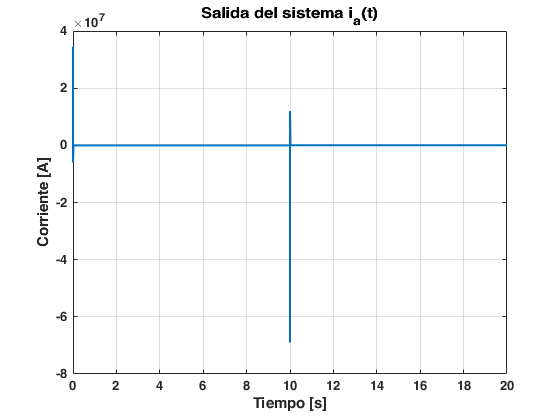

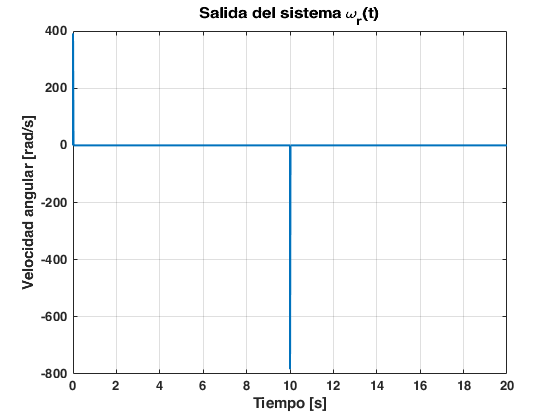

plot(t,ia,'LineWidth',1.5);
title('Salida del sistema i_a(t)')
xlabel('Tiempo [s]')
ylabel('Corriente [A]')
grid